fid=fopen('Comp_All_Scenario.txt');
tline = fgetl(fid);
tlines = cell(0,1);
while ischar(tline)
    tlines{end+1,1} = tline;
    tline = fgetl(fid);
end
fclose(fid);



%for j=1:3:(length(tlines)-3)
j=1;
LD_Nodes = [str2num(tlines{j}) ; str2num(tlines{j+1}) ; str2num(tlines{j+2})]';
%DEN=20599s,22330s,22113s,23916s


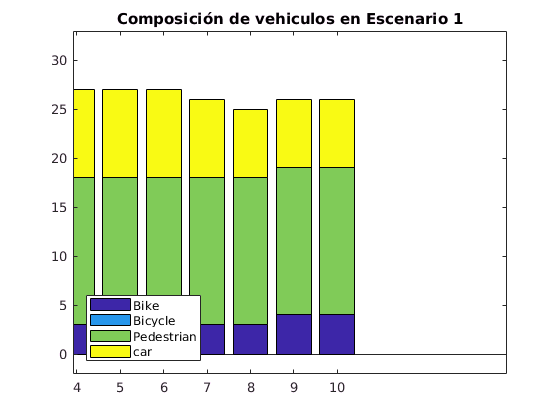

ind2 = zeros(4,10);
ini_T = min(LD_Nodes(:,1));
for i=1:length(LD_Nodes)
    ini_n = LD_Nodes(i,1)-ini_T+1;
    fin_n = LD_Nodes(i,2)-ini_T;
    ind2(LD_Nodes(i,3),ini_n:fin_n)= ind2(LD_Nodes(i,3),ini_n:fin_n)+1;
  
end 

%sum(ind2)

figure (1)
bar(ind2','stacked')
title('Composición de vehiculos en Escenario 1')
legend('Bike','Bicycle','Pedestrian','car','Location','SouthWest');
xlim([0 10])


%end
%Buscar 9,20,28,37

